# Atividade 07 - SYSID

Aluno: Pedro Henrique Cardoso Paulo

Professor: Helon

## Passo 1 - Inicialndo código e importando casadi

### 1.1 - Iniciando prompt

clc
clear
close all

addpath(genpath('casadi/'))

import casadi.*

## Passo 2 - Carregando os dados

### 2.1 - Carregando dados

%%%%%%%%%%%% load data %%%%%%%%%%%%%%%%%%%%%
% File to load
load('DATA_EMPS')
% Variables are:
% qm = motor position (measured through the motor encoder)
% qg = the reference position
% t = time
% vir = motor voltage (output of the controller)

### 2.2 - Filtrando os dados

% Construction of the vector measurements
Force1 = gtau*vir; % Motor force

decimate = 5; % see Forgione, Piga, EJC 59 (2021) 69-81
u_data = Force1(1:decimate:end);
y_data = qm(1:decimate:end);
t      = t(1:decimate:end);

## Passo 3 - Construindo o modelo

### 3.1 - Extraindo parâmetros gerais

N  = length(t);  % Number of samples
Ts = round(t(2)-t(1),3);  % sampling time (seconds)
fs = 1/Ts;       % Sampling frequency [hz]

### 3.2 - Iniciando condições iniciais

x0 = DM([qm(1),0]); % initial condition for simulation

### 3.3 - Declarando estados e inputs

q  = MX.sym('q');
dq = MX.sym('dq');
u  = MX.sym('u');

states = [q;dq];
controls = u;

### 3.4 - Declarando parâmetros do modelo

Mn    = MX.sym('Mn');
Fvn   = MX.sym('Fvn');
Fcn   = MX.sym('Fcn');
ofstn = MX.sym('ofstn');

params   = [Mn;Fvn;Fcn;ofstn];
parammax = [150; 300; 40;  15];
parammin = [ 30; 100;  0; -15];

nparam = length(params);
param_guess = rand(nparam,1);

lbx = zeros(nparam,1);
ubx = ones(nparam,1);

M    = denorm(Mn,   parammax(1),parammin(1));
Fv   = denorm(Fvn,  parammax(2),parammin(2));
Fc   = denorm(Fcn,  parammax(3),parammin(3));
ofst = denorm(ofstn,parammax(4),parammin(4));

### 3.5 - Definindo equação que rege o modelo e construindo a ODE

rhs = [dq; (u-Fv*dq-Fc*sign(dq)-ofst)/M]; %Aqui está declarado o modelo de atrito

% Form an ode function
ode = Function('ode',{states,controls,params},{rhs});

## Passo 4 - Construindo o simulador

### 4.1 - Extração de parâmetros gerais da simulação

N_steps_per_sample = 10;
dt = 1/fs/N_steps_per_sample;

### 3.2 - Configurando integrador (RK4)

% Build an integrator for this system: Runge Kutta 4 integrator
k1 = ode(states,controls,params);
k2 = ode(states+dt/2.0*k1,controls,params);
k3 = ode(states+dt/2.0*k2,controls,params);
k4 = ode(states+dt*k3,controls,params);

states_final = states+dt/6.0*(k1+2*k2+2*k3+k4);

### 3.3 - Mapeando variáveis em funções

% Create a function that simulates one step propagation in a sample
one_step = Function('one_step',{states, controls, params},{states_final});

X = states;
for i=1:N_steps_per_sample
    X = one_step(X, controls, params);
end
%
% % Create a function that simulates all step propagation on a sample
one_sample = Function('one_sample',{states, controls, params}, {X});
%
% speedup trick: expand into scalar operations
one_sample = one_sample.expand();

## Passo 5 - Executando simulação

all_samples = one_sample.mapaccum('all_samples', N);

## Passo 6 - Identificando o sistema

opts = struct;
opts.ipopt.acceptable_tol = 1e-4;
opts.ipopt.acceptable_obj_change_tol = 1e-4;

single_multiple = 0;
switch single_multiple
    case 1           
        %%%%%%%%%%%% single shooting strategy %%%%%%%%%%
        X_symbolic = all_samples(x0, u_data, repmat(params,1,N));
        
        e = y_data-X_symbolic(1,:)';
        
        J = 1/N*dot(e,e);
        nlp = struct('x', params, 'f', J);
        
        solver = nlpsol('solver', 'ipopt', nlp, opts);
        
        sol = solver('x0', param_guess, 'lbx', lbx,'ubx', ubx);
        
        % parametros identificados:
        paramhat = sol.x.full;
    otherwise
        %%%%%%%%%%%% multiple shooting strategy %%%%%%%%%%
        % % All states become decision variables
        X = MX.sym('X', 2, N);

        res = one_sample.map(N, 'thread', 4);
        Xn = res(X, u_data', repmat(params,1,N));

        gaps = Xn(:,1:end-1)-X(:,2:end);

        e = y_data-Xn(1,:)';

        V = veccat(params, X);

        J = 1/N*dot(e,e);

        nlp = struct('x',V, 'f',J,'g',vec(gaps));

        % Multipleshooting allows for careful initialization
        yd = diff(y_data)*fs;
        X_guess = [ y_data  [yd;yd(end)]]';

        param_guess = [param_guess(:);X_guess(:)];

        solver = nlpsol('solver','ipopt', nlp, opts);

        sol = solver('x0',param_guess,'lbg',0,'ubg',0);
        solx = sol.x.full;
        paramhat = solx(1:nparam);
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:    64584
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:    54669

Total number of variables............................:     9942
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     9936
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

## Passo 7 - Analisando os resultados

### 7.1 - Visualizando resultados do ajuste

Mhat    = denorm(paramhat(1),parammax(1),parammin(1));
Fvhat   = denorm(paramhat(2),parammax(2),parammin(2));
Fchat   = denorm(paramhat(3),parammax(3),parammin(3));
ofsthat = denorm(paramhat(4),parammax(4),parammin(4));

disp('Parametros identificados:')

Parametros identificados:


[Mhat, Fvhat, Fchat, ofsthat]

ans =    96.0145  213.9603   19.4100   -3.2793


disp('Parametros IDIM:')

Parametros IDIM:


paramhatIDIM = [95.1089, 203.5034, 20.3935, -3.1648]';
paramhatIDIM' 

ans =    95.1089  203.5034   20.3935   -3.1648


paramhatIDIM = normalize(paramhatIDIM,parammax,parammin); % simulation

### 7.2 - Comparando soluções

Xhat = all_samples(x0, u_data, repmat(paramhat,1,N));
Xhat = Xhat.full;
yhat = Xhat(1,:)';

XhatIDIM = all_samples(x0, u_data, repmat(paramhatIDIM,1,N));
XhatIDIM = XhatIDIM.full;
yhatIDIM = XhatIDIM(1,:)';

#### 7.2.1 - Comparação de resultados

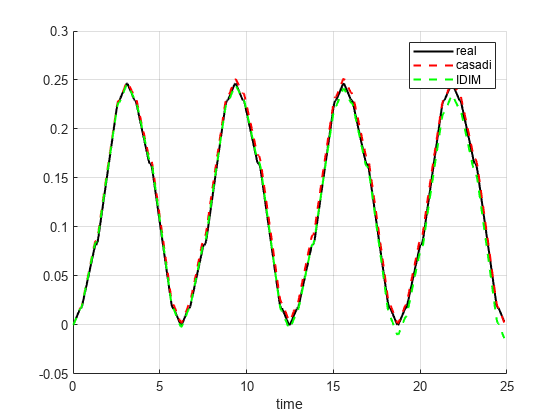

figure
hold on
plot(t,y_data,'k-','linewidth',1.5)
plot(t,yhat,'r--','linewidth',1.5)
plot(t,yhatIDIM,'g--','linewidth',1.5)
grid on
xlabel('time')
legend({'real','casadi','IDIM'},'location','best')

#### 7.2.2 - Comparação dos erros

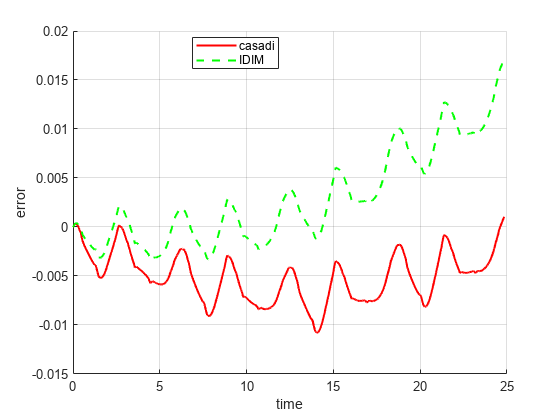

figure
hold on
plot(t,y_data-yhat,'r-','linewidth',1.5)
plot(t,y_data-yhatIDIM,'g--','linewidth',1.5)
grid on
xlabel('time')
ylabel('error')
legend({'casadi','IDIM'},'location','best')

## Passo 8 - Comparando com o modelo de Tustin

Essa comparação será feita por meio de uma rodada nova do script com nova comparação. O modelo é como segue:


$$F^s_T=F_V\dot{q}+F_C * sign(\dot{q}) + (F_S - F_C)e^{-\frac{\dot{q}}{v_s}}$$


### 8.1 - Re-executando simulação com novo modelo

%%%%%%%%%%%% MODELING %%%%%%%%%%%%%%%%%%%%%
q  = MX.sym('q');
dq = MX.sym('dq');
u  = MX.sym('u');

states = [q;dq];
controls = u;

Mn    = MX.sym('Mn');
Fvn   = MX.sym('Fvn');
Fcn   = MX.sym('Fcn');
Fsn   = MX.sym('Fsn');
vsn   = MX.sym('vsn');
ofstn = MX.sym('ofstn');

params   = [Mn;Fvn;Fcn;Fsn;vsn;ofstn];
parammax = [150; 300; 40;100; 50;  15];
parammin = [ 30; 100;  0;  0;  0; -15];

nparam = length(params);
param_guess = rand(nparam,1);

lbx = zeros(nparam,1);
ubx = ones(nparam,1);

M    = denorm(Mn,   parammax(1),parammin(1));
Fv   = denorm(Fvn,  parammax(2),parammin(2));
Fc   = denorm(Fcn,  parammax(3),parammin(3));
Fs   = denorm(Fcn,  parammax(4),parammin(4));
vs   = denorm(Fcn,  parammax(5),parammin(5));
ofst = denorm(ofstn,parammax(6),parammin(6));

rhs = [dq; (u-Fv*dq-Fc*sign(dq)-(Fs-Fc)*exp(-abs(dq)/vs)-ofst)/M];

% Form an ode function
ode = Function('ode',{states,controls,params},{rhs});

%%%%%%%%%%%% Creating a simulator %%%%%%%%%%
N_steps_per_sample = 10;
dt = 1/fs/N_steps_per_sample;

% Build an integrator for this system: Runge Kutta 4 integrator
k1 = ode(states,controls,params);
k2 = ode(states+dt/2.0*k1,controls,params);
k3 = ode(states+dt/2.0*k2,controls,params);
k4 = ode(states+dt*k3,controls,params);

states_final = states+dt/6.0*(k1+2*k2+2*k3+k4);

% Create a function that simulates one step propagation in a sample
one_step = Function('one_step',{states, controls, params},{states_final});

X = states;
for i=1:N_steps_per_sample
    X = one_step(X, controls, params);
end
%
% % Create a function that simulates all step propagation on a sample
one_sample = Function('one_sample',{states, controls, params}, {X});
%
% speedup trick: expand into scalar operations
one_sample = one_sample.expand();

%%%%%%%%%%%% Simulating the system %%%%%%%%%%

all_samples = one_sample.mapaccum('all_samples', N);

%%%%%%%%%%%% Identifying the simulated system %%%%%%%%%%
opts = struct;
% opts.ipopt.max_iter = 15;
% opts.ipopt.print_level = 3;%0,3
% opts.print_time = 1;
opts.ipopt.acceptable_tol = 1e-4;
opts.ipopt.acceptable_obj_change_tol = 1e-4;

single_multiple = 0;
switch single_multiple
    case 1           
        %%%%%%%%%%%% single shooting strategy %%%%%%%%%%
        X_symbolic = all_samples(x0, u_data, repmat(params,1,N));
        
        e = y_data-X_symbolic(1,:)';
        
        J = 1/N*dot(e,e);
        nlp = struct('x', params, 'f', J);
        
        solver = nlpsol('solver', 'ipopt', nlp, opts);
        
        sol = solver('x0', param_guess, 'lbx', lbx,'ubx', ubx);
        
        % parametros identificados:
        paramhat = sol.x.full;
    otherwise
        %%%%%%%%%%%% multiple shooting strategy %%%%%%%%%%
        % % All states become decision variables
        X = MX.sym('X', 2, N);

        res = one_sample.map(N, 'thread', 4);
        Xn = res(X, u_data', repmat(params,1,N));

        gaps = Xn(:,1:end-1)-X(:,2:end);

        e = y_data-Xn(1,:)';

        V = veccat(params, X);

        J = 1/N*dot(e,e);

        nlp = struct('x',V, 'f',J,'g',vec(gaps));

        % Multipleshooting allows for careful initialization
        yd = diff(y_data)*fs;
        X_guess = [ y_data  [yd;yd(end)]]';

        param_guess = [param_guess(:);X_guess(:)];

        solver = nlpsol('solver','ipopt', nlp, opts);

        sol = solver('x0',param_guess,'lbg',0,'ubg',0);
        solx = sol.x.full;
        paramhat = solx(1:nparam);
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:    64584
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:    54669

Total number of variables............................:     9944
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     9936
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1


%% analisa resultado

Mhat    = denorm(paramhat(1),parammax(1),parammin(1));
Fvhat   = denorm(paramhat(2),parammax(2),parammin(2));
Fchat   = denorm(paramhat(3),parammax(3),parammin(3));
Fshat   = denorm(paramhat(4),parammax(4),parammin(4));
vshat   = denorm(paramhat(5),parammax(5),parammin(5));
ofsthat = denorm(paramhat(6),parammax(6),parammin(6));

disp('Parametros identificados:')

Parametros identificados:


[Mhat, Fvhat, Fchat, Fshat, vshat, ofsthat]

ans =    95.8663  212.8751   19.5162   52.8533    8.2824  -32.4608


%% compare both solutions (IDIM vs. CASADI)

Xhat2 = all_samples(x0, u_data, repmat(paramhat,1,N));
Xhat2 = Xhat2.full;
yhat2 = Xhat(1,:)';

### 8.2 - Comparando resultados

#### 8.2.1 - Comparação de resultados

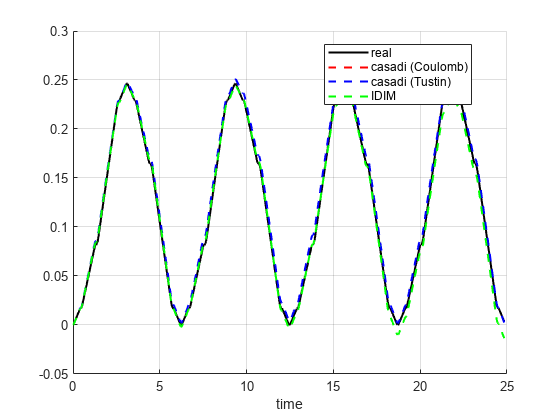

figure
hold on
plot(t,y_data,'k-','linewidth',1.5)
plot(t,yhat,'r--','linewidth',1.5)
plot(t,yhat2,'b--','linewidth',1.5)
plot(t,yhatIDIM,'g--','linewidth',1.5)
grid on
xlabel('time')
legend({'real','casadi (Coulomb)','casadi (Tustin)','IDIM'},'location','best')

#### 8.2.2 - Comparação dos erros

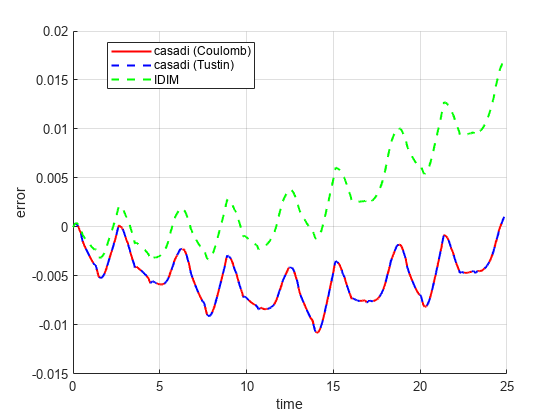

figure
hold on
plot(t,y_data-yhat,'r-','linewidth',1.5)
plot(t,y_data-yhat2,'b--','linewidth',1.5)
plot(t,y_data-yhatIDIM,'g--','linewidth',1.5)
grid on
xlabel('time')
ylabel('error')
legend({'casadi (Coulomb)','casadi (Tustin)','IDIM'},'location','best')

## Conclusões

- Não houve significativo ganho em migrar para o modelo de Tustin

- Parâmetros parecem ter se compensado, com um offset maior compensando o surgimento do atrito de Tustin

- Valor de vs, que reduz o peso do atrito

- Em ambos os casos, casadi permitiu um ajuste bom do modelo

## Funções de suporte

function v = denorm(vn,vmax,vmin)
    v = vmin + (vmax-vmin)*vn;
end
function vn = normalize(v,vmax,vmin)
    vn = (v - vmin) ./ (vmax-vmin);
end